# Cvičení 5 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

T = readtable('data.csv','ReadVariableNames',true);

## 1. Vizualizace dat

Vizualizaci proveďte s důrazem na čitelnost a přehlednost. Cílem je vidět co nejlépe případné rozdíly mezi skupinami. Doporučujeme využít zobrazení pomocí `boxplot` či `boxchart` a rozvržení grafů pomocí funkce `tiledlayout`.

**Vizualizaci proveďte pro všechny 4 měřené akustické parametry: RI, DVA, MPT a stdF0.**

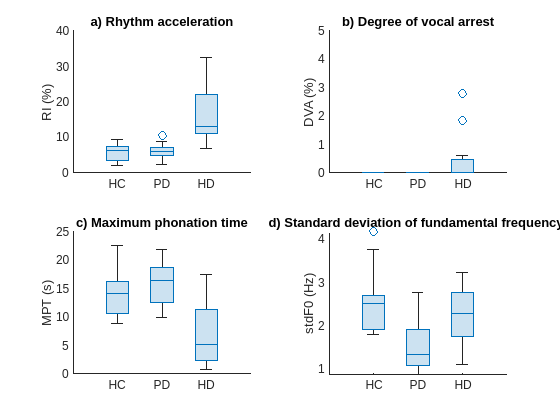

% Váš kód pro vizualizaci
% help tiledlayout
% help boxplot
% help boxchart


tiledlayout("flow")
nexttile
boxchart([T{T.group == "HC", "RI"} T{T.group == "PD", "RI"} T{T.group == "HD", "RI"}])
set(gca, 'XTickLabel', {'HC', 'PD', 'HD'})
title('a) Rhythm acceleration'); ylabel('RI (%)')

nexttile
boxchart([T{T.group == "HC", "DVA"} T{T.group == "PD", "DVA"} T{T.group == "HD", "DVA"}])
ylim([0 5])
set(gca, 'XTickLabel', {'HC', 'PD', 'HD'})

title('b) Degree of vocal arrest'); ylabel('DVA (%)')

nexttile
boxchart([T{T.group == "HC", "MPT"} T{T.group == "PD", "MPT"} T{T.group == "HD", "MPT"}])
set(gca, 'XTickLabel', {'HC', 'PD', 'HD'})
title('c) Maximum phonation time'); ylabel('MPT (s)')

nexttile
boxchart([T{T.group == "HC", "stdF0"} T{T.group == "PD", "stdF0"} T{T.group == "HD", "stdF0"}])
set(gca, 'XTickLabel', {'HC', 'PD', 'HD'})
title('d) Standard deviation of fundamental frequency '); ylabel('stdF0 (Hz)')

**Otázky:**

- Pohledem vyhodnoťte jestli jednotlivé skupiny vykazují normální rozdělení (respektive  spíše pokud nějaká skupina vykazuje **významné odchylky od normálního rozdělení**) a zdali je mezi skupinami pro každý z parametrů vidět nějaký **efekt** (silný/slabý, či z hlediska pacienta pozitivní/negativní, …).

RI - normální rozdělení, silný efekt pro HD, to je ale silně skewed.

DVA - není normální, slabý efekt pro HD, má občas nenulovou hodnotu

MPT - normální rozdělení silný efekt pro HD, to je ale silně skewed

stdF0 - normální rozdělení, silný efekt pro PD

## 2. Ověření podmínek pro ANOVA

### 2a Ověření Normality vstupních dat

- Vyberte vhodný test, viz předešlé cvičení a přednáška.

- Není třeba vypisovat hypotézy, pouze si dejte pozor – u jednotlivých testů se liší (viz např. rozdíl mezi `kstest` a `swtest`).

- Výsledky testu korektně reportujte.

% Váš kód pro ověření normality
alpha = 0.05;

res = table('Size',[0, 4], 'VariableTypes', ["string", "string", "string", "logical"], 'VariableNames', ["Group", "Data", "SW test report", "Is normal"]);

for group=["HC", "PD", "HD"]
    for data=["RI", "DVA", "MPT", "stdF0"]
        [H, pValue, SWstatistic] = swtest(T{T.group == group, data}, alpha);
        res = [res; {group, data, sprintf('swtest(W = %.2f, p = %.2f)',SWstatistic, pValue), ~H}];
    end
end

disp(res)

    Group     Data             SW test report           Is normal
    _____    _______    ____________________________    _________

    "HC"     "RI"       "swtest(W = 0.95, p = 0.51)"      true   
    "HC"     "DVA"      "swtest(W = NaN, p = NaN)"        true   
    "HC"     "MPT"      "swtest(W = 0.91, p = 0.16)"      true   
    "HC"     "stdF0"    "swtest(W = 0.87, p = 0.03)"      false  
    "PD"     "RI"       "swtest(W = 0.92, p = 0.21)"      true   
    "PD"     "DVA"      "swtest(W = NaN, p = NaN)"        true   
    "PD"     "MPT"      "swtest(W = 0.95, p = 0.53)"      true   
    "PD"     "stdF0"    "swtest(W = 0.90, p = 0.11)"      true   
    "HD"     "RI"       "swtest(W = 0.86, p = 0.02)"      false  
    "HD"     "DVA"      "swtest(W = 0.36, p = 0.00)"      false  
    "HD"     "MPT"      "swtest(W = 0.86, p = 0.03)"      false  
    "

Zde vidíme, že používat DVA je úplně zbytečné, jelikož ve 2/3 skupin nemáme data

### 2b Oveření homogenity rozptylů

- **BUĎ: **Korektním způsobem argumentujte, proč lze požadavek na homogenitu rozptylů považovat za splněný i bez provádění testů. *Toto odůvodnění zapište slovy.*

- **NEBO: **Otestujte rovnost rozptylů pomocí vhodné analýzy – Bartlettova nebo Levenova testu. Výsledek testu korektně reportujte a interpretujte. Nápověda: funkce `vartestn`.

variable: RI

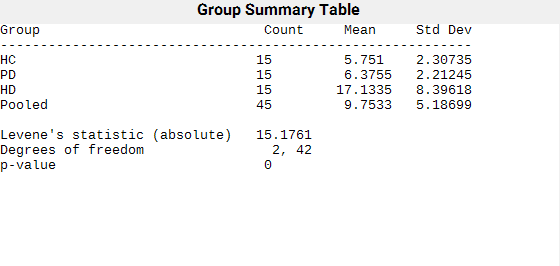

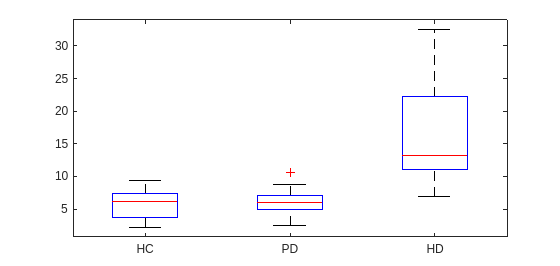

variable: MPT

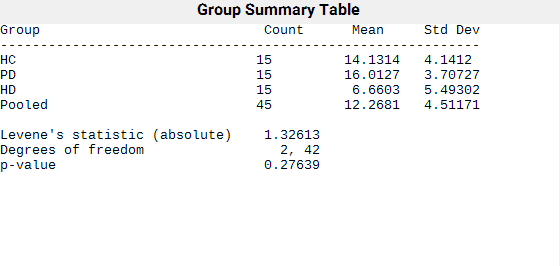

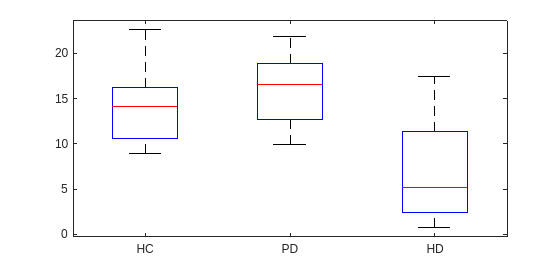

variable: stdF0

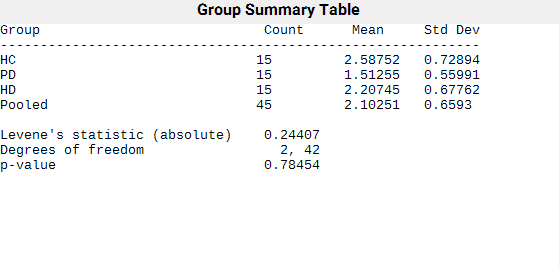

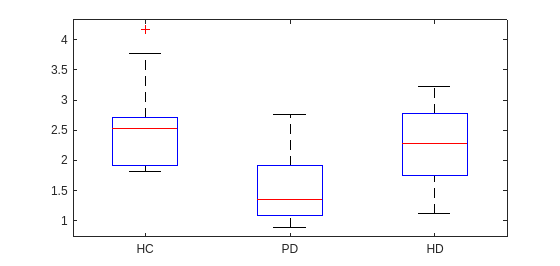

% Váš kód pro ověření homoskedasticity, pokud budete ověřovat pomocí testu

for data=["RI", "MPT", "stdF0"]
    fprintf("variable: %s", data)
    p = vartestn(T{:, data}, T.group, "TestType","LeveneAbsolute");

end

Z testů vychází, že pouze MPT a stdF0 jsou homoskedasticitní.

## 3. Úloha

Chtěli bychom dokázat, že lze rozlišit zdravé lidi (HC), pacienty s PD a pacienty s HD jen na základě nahrávek řečových testů, a případně i potvrdit, že změny v akustických parametrech úzce souvisí s celkovým klinickým hodnocením stavu pacienta.

**Použijte informace, které jste získali v předchozích částech, pro výběr vhodných testů a následnou interpretaci. Odpovězte na následující otázky:**

- *Lze mezi sebou statisticky významně rozlišit skupiny HC, PD a HD pomocí parametrů RI, MPT, DVA nebo stdF0? V této části hledáte jen odpověď ****ano či ne*** ***pomocí vhodného testu.***

- *Pokud jste zjistili, že pomocí nějakého parametru lze od sebe skupiny odlišit, ****jaké dvojice skupin vykazují mezi sebou statisticky významné rozdíly****?*

- *Jaký je ****vztah mezi zrychlováním řeči**** (parametr RI****) a klinickým hodnocením lékařem**** (hodnoty z dotazníků UPDRS a UHDRS)? Odpovídá horší schopnost udržet tempo řeči vyššímu motorickému postižení, hodnocenému lékařem?*

- Výběr statistických testů **odůvodněte**. 

- Pro opakované testy stačí zapsat testové hypotézy **jen jednou**.

- Reportujte výsledky testů **korektně** (využijte přednášku).

- Výsledky testů **interpretujte** s ohledem na předešlá rozhodnutí o normalitě, homoskedasticitě, výběru testu a výběru post-hoc metody.

**1)**

H0: Měřené skupiny mají stejný průměr.

H1: Mezi měřenými skupinami je signifikantní rozdíl.

variable: RI

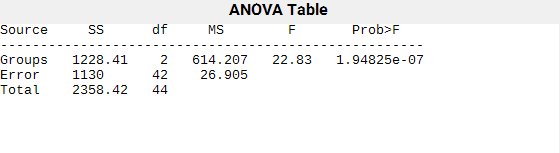

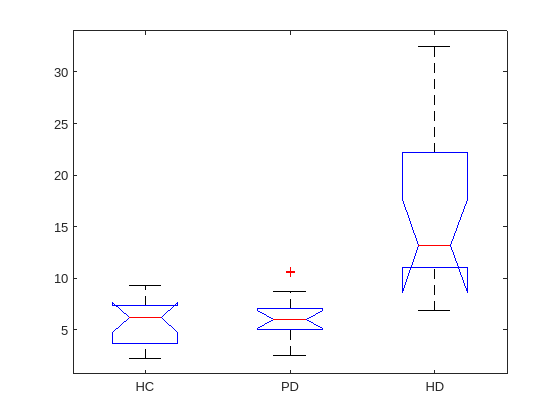

variable: MPT

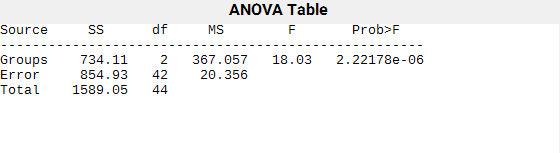

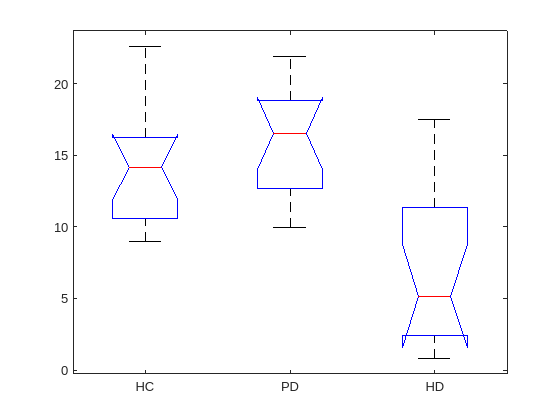

variable: stdF0

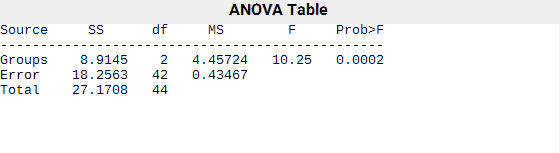

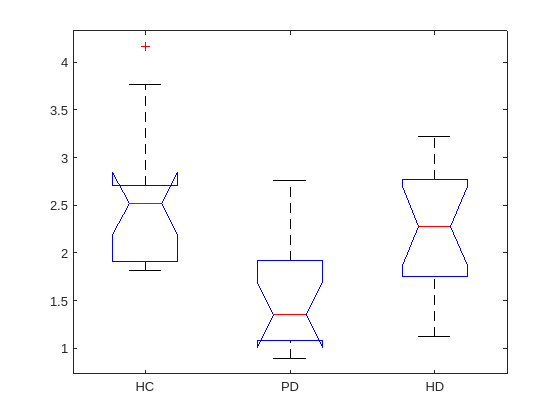

% Váš kód
for data=["RI", "MPT", "stdF0"]
    fprintf("variable: %s", data)
    [p,tbl,stats] = anova1(T{:, data}, T.group);
end

U všech parametrů zamítáme H0 ve prospěch H1.

**2)**

H0: Rozdíl průměrů daných dvou měřených skupin není signifikantní.

for data=["RI", "MPT", "stdF0"]
    fprintf("variable: %s\n", data)
    [~,~,stats] = anova1(T{:, data}, T.group, "off");
    [results, means, ~, gnames] = multcompare(stats, Display="off");
    tbl = array2table([results,means],"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value","Mean","Standard Error"]);
    tbl.("Group A")=gnames(tbl.("Group A"));
    tbl.("Group B")=gnames(tbl.("Group B"));
    disp(tbl)
end

variable: RI


    Group A    Group B    Lower Limit      A-B       Upper Limit     P-value       Mean     Standard Error
    _______    _______    ___________    ________    ___________    __________    ______    ______________

    {'HC'}     {'PD'}        -5.226      -0.62453        3.977         0.94191     5.751        1.3393    
    {'HC'}     {'HD'}       -15.984       -11.382      -6.7809      1.1405e-06    6.3755        1.3393    
    {'PD'}     {'HD'}       -15.359       -10.758      -6.1564      3.3873e-06    17.133        1.3393    



variable: MPT


    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value       Mean     Standard Error
    _______    _______    ___________    _______    ___________    __________    ______    ______________

    {'HC'}     {'PD'}       -5.8838      -1.8813      2.1212           0.4941    14.131        1.1649    
    {'HC'}     {'HD'}        3.4686       7.4711      11.474       0.00013819    16.013        1.1649    
    {'PD'}     {'HD'}        5.3499       9.3524      13.355       3.4215e-06    6.6603        1.1649    



variable: stdF0


    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value       Mean     Standard Error
    _______    _______    ___________    _______    ___________    __________    ______    ______________

    {'HC'}     {'PD'}       0.49009        1.075       1.6598      0.00017209    2.5875       0.17023    
    {'HC'}     {'HD'}      -0.20481      0.38007      0.96495         0.26592    1.5125       0.17023    
    {'PD'}     {'HD'}       -1.2798      -0.6949     -0.11002        0.016532    2.2075       0.17023    



U proměnných *RI *a *MPT* je skupina HD signifaktně rozdílná od ostatních

U proměnné stdF0 je signifikantně rozdílná skupina PD

**3)**

H0: průměrný rozdíl RI a UPDRS (UHDRS) je nulový.

[~, p, ~, stats] = ttest(T{T.group == "PD", "UPDRS_III"}, T{T.group == "PD", "RI"});
fprintf("UPDRS_III\nt(%.0f)=%.4f, p = %.4f", stats.df, stats.tstat, p)

UPDRS_III
t(14)=7.5219, p = 0.0000

[~, p, ~, stats] = ttest(T{T.group == "HD", "UHDRS"}, T{T.group == "HD", "RI"});
fprintf("UHDRS\nt(%.0f)=%.4f, p = %.4f", stats.df, stats.tstat, p)

UHDRS
t(14)=1.1419, p = 0.2726

H0 zamítáme pro UPDRS III, tedy zde měřený parametr RI odpovídá klinickému hodnocemí u pacientů s PD. Naopak u pacientů s HD RI odpovídá klinickému hodnocení.